## Wind tunnel data analysis and comparison to Literature

Import data files from windtunnel test

clc
close all
clearvars
addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\RC Testbench Data'))
MN3510_MF1302R_0 = readtable('UDP_2021-11-16_144348.csv');

MN3510_MF1302R_90 = readtable('UDP_2021-11-16_145014.csv');

MN3510_MF1302R_0_w = readtable('meas30.txt');
MN3510_MF1302R_90_w = readtable('meas31.txt');

d = 339.8e-3;
r = d/2;
rpm2rads= 2*pi/60;

Find sync time shift between wind tunnel and rc test benchmark data set based on thrust.

Rename variables for more straight forward analysis

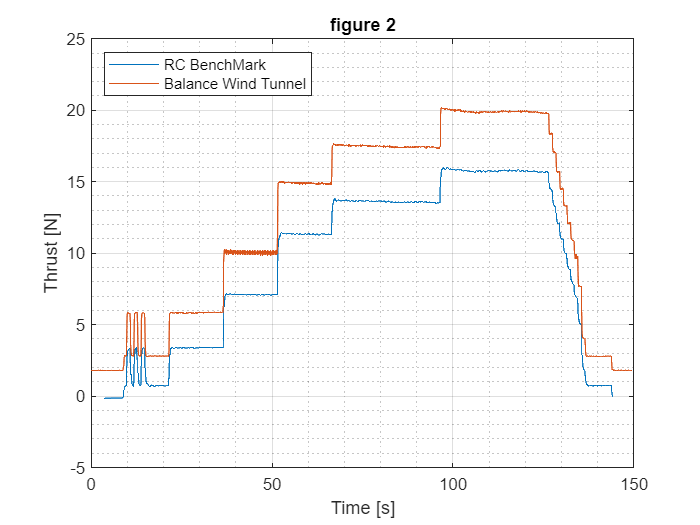

rpm_acc = 0.005; % Tried to filter based on RPM readings but Optical is way too off
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 0 deg test 
range_00     = (abs((MN3510_MF1302R_0.MotorElectricalSpeed_RPM_(1:end-1)-MN3510_MF1302R_0.MotorElectricalSpeed_RPM_(2:end))./MN3510_MF1302R_0.MotorElectricalSpeed_RPM_(1:end-1))<rpm_acc);
time_wt_00   = MN3510_MF1302R_0_w.Var1;
thrust_wt_00 = MN3510_MF1302R_0_w.Var6;
as_wt_00     = MN3510_MF1302R_0_w.Var12;

time_rc_00   = MN3510_MF1302R_0.Time_s_(range_00);
thrust_rc_00 = MN3510_MF1302R_0.Thrust_N_(range_00);
torque_rc_00 = MN3510_MF1302R_0.Torque_N_m_(range_00);
rpm_O_00     = MN3510_MF1302R_0.MotorOpticalSpeed_RPM_(range_00);
rpm_E_00     = MN3510_MF1302R_0.MotorElectricalSpeed_RPM_(range_00);
n_plr_00     = MN3510_MF1302R_0.PropellerMech_Efficiency_N_W_(range_00);
P_mech_00    = MN3510_MF1302R_0.MechanicalPower_W_(range_00);
pwm_00       = MN3510_MF1302R_0.ESCSignal__s_(range_00);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 90 deg test 
range_90     = (abs((MN3510_MF1302R_90.MotorElectricalSpeed_RPM_(1:end-1)-MN3510_MF1302R_90.MotorElectricalSpeed_RPM_(2:end))./MN3510_MF1302R_90.MotorElectricalSpeed_RPM_(1:end-1))<rpm_acc);
time_wt_90   = MN3510_MF1302R_90_w.Var1;
thrust_wt_90 = MN3510_MF1302R_90_w.Var6;
as_wt_90     = MN3510_MF1302R_90_w.Var12;

time_rc_90   = MN3510_MF1302R_90.Time_s_(range_90);
thrust_rc_90 = MN3510_MF1302R_90.Thrust_N_(range_90);
torque_rc_90 = MN3510_MF1302R_90.Torque_N_m_(range_90);
rpm_O_90     = MN3510_MF1302R_90.MotorOpticalSpeed_RPM_(range_90);
rpm_E_90     = MN3510_MF1302R_90.MotorElectricalSpeed_RPM_(range_90);
n_plr_90     = MN3510_MF1302R_90.PropellerMech_Efficiency_N_W_(range_90);
P_mech_90    = MN3510_MF1302R_90.MechanicalPower_W_(range_90);
pwm_90       = MN3510_MF1302R_90.ESCSignal__s_(range_90);

delay_0      = syncher(time_wt_00,thrust_wt_00,time_rc_00,thrust_rc_00,1);

delay_90     = syncher(time_wt_90,thrust_wt_90,time_rc_90,thrust_rc_90,0);

as_rc_00     = interp1(time_wt_00+delay_0, as_wt_00, time_rc_00 );
as_rc_90     = interp1(time_wt_90+delay_90, as_wt_90, time_rc_90 );

Check trend of results from the windtunnel test

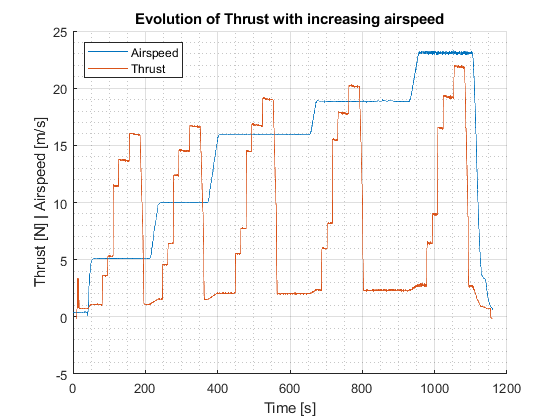

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(5)
clf
hold on
plot(time_wt_90+delay_90,as_wt_90)
plot(time_rc_90,thrust_rc_90)
grid on
grid minor
ylabel('Thrust [N] | Airspeed [m/s]')
xlabel('Time [s]')
title('Evolution of Thrust with increasing airspeed')
legend('Airspeed','Thrust','Location','northwest')

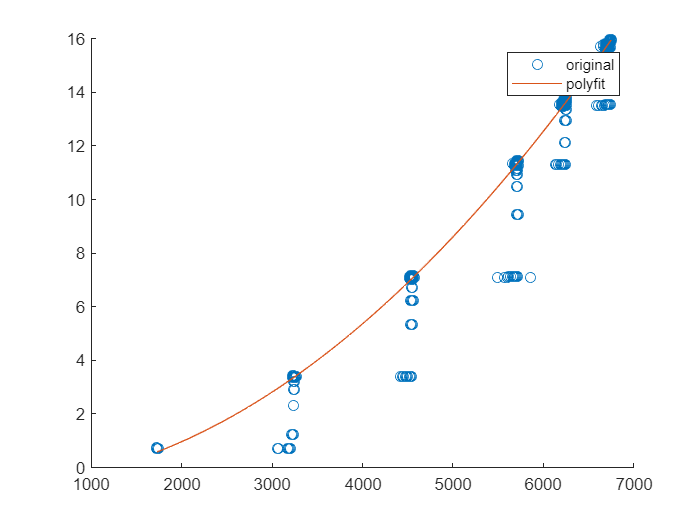

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(6)
clf
findchangepts(as_wt_90,'MaxNumChanges',6)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
deg=2;
t_interest = [20,126];
idx_s_0 = find(time_rc_00>=t_interest(1),1,'first');
idx_e_0 = find(time_rc_00>=t_interest(2),1,'first');
  
v_q = [5,10,16,19,23];
rpm_lim = [min(rpm_E_00(idx_s_0:idx_e_0)) max(rpm_E_00(idx_s_0:idx_e_0))]; %[min(rpm_E_90) max(rpm_E_90)];
pwm_lim = [min(pwm_00(idx_s_0:idx_e_0)) max(pwm_00(idx_s_0:idx_e_0))];
as_lim  = [min(as_wt_90) max(as_wt_90)];
rpm_q = linspace(rpm_lim(1),rpm_lim(2),100);
pwm_q = linspace(pwm_lim(1),pwm_lim(2),100);
as_q  = linspace(as_lim(1),as_lim(2),100);
[polycoeffs_0, poly_T_0] = poly_gen(rpm_E_00(idx_s_0:idx_e_0),thrust_rc_00(idx_s_0:idx_e_0),deg,rpm_q,1);

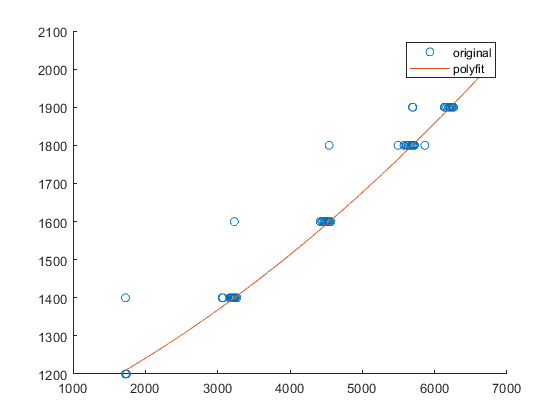

[polycoeffs_pwm_0, poly_pwm_0] = poly_gen(rpm_E_00(idx_s_0:idx_e_0),pwm_00(idx_s_0:idx_e_0),deg,rpm_q,1);


ipt = findchangepts(as_wt_90,'MaxNumChanges',6);

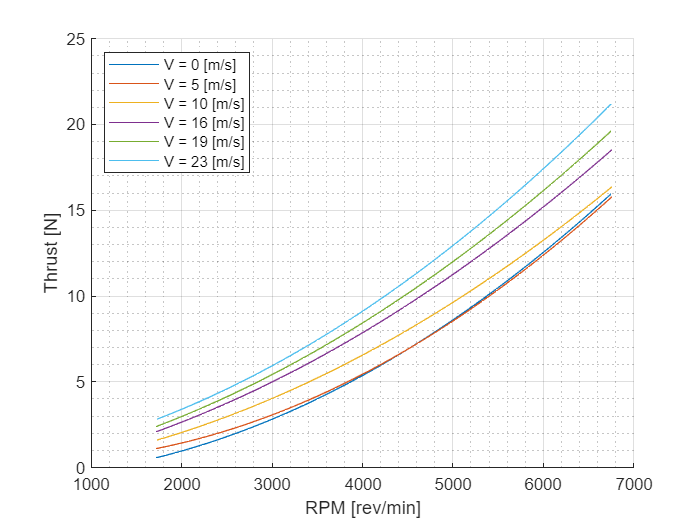

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
range_90= find(rpm_E_90 >4500);

polycoeffs = zeros(deg+1, size(v_q,2));
polycoeffs_Mx = zeros(deg+1, size(v_q,2));
polycoeffs_Pm = zeros(deg+1, size(v_q,2));
polycoeffs_n_plr = zeros(deg+1, size(v_q,2));
polycoeffs_pwm   = zeros(deg+1, size(v_q,2));
T_experiment = zeros(size(rpm_q,2), size(v_q,2));
Mx_experiment = zeros(size(rpm_q,2), size(v_q,2));
P_mech_experiment = zeros(size(rpm_q,2), size(v_q,2));
n_plr_experiment = zeros(size(rpm_q,2), size(v_q,2));
rcCl_experiment = zeros(1, size(v_q,2));
pwm_experiment = zeros(size(rpm_q,2), size(v_q,2));
ss_shift = 5;%round(5/mean(gradient(time_rc_90)));
debug = 0;
js = 1;
je = size(v_q,2);
if debug
    v_db = 5;
    js = find(v_q==v_db);
    je = js;  
end

figure(7)
clf
hold on
if ~debug
    plot(rpm_q, poly_T_0)
end

idx_record = zeros(1,size(v_q,2)+1);
for i = js:je
    idx_s = find(time_rc_90>=(time_wt_90(ipt(i))+delay_90+ss_shift).',1,'first');
    idx_e = find(time_rc_90>=(time_wt_90(ipt(i+1))+delay_90-ss_shift).',1,'first');
    idx_record(i)= idx_s;idx_record(i+1)= idx_e;
    [polycoeffs(:,i), T_experiment(:,i)] = poly_gen(rpm_E_90(idx_s:idx_e),thrust_rc_90(idx_s:idx_e),deg,rpm_q,debug);
    [polycoeffs_Mx(:,i), Mx_experiment(:,i)] = poly_gen(rpm_E_90(idx_s:idx_e),torque_rc_90(idx_s:idx_e),deg,rpm_q,debug);
    [polycoeffs_Pm(:,i), P_mech_experiment(:,i)] = poly_gen(rpm_E_90(idx_s:idx_e),P_mech_90(idx_s:idx_e),deg,rpm_q,debug);
    [polycoeffs_n_plr(:,i), n_plr_experiment(:,i)] = poly_gen(rpm_E_90(idx_s:idx_e),n_plr_90(idx_s:idx_e),deg,rpm_q,debug);
    [polycoeffs_pwm(:,i),pwm_experiment(:,i)] = poly_gen(rpm_E_90(idx_s:idx_e),pwm_90(idx_s:idx_e),deg,rpm_q,debug);


    true_range = intersect([idx_s:idx_e], range_90);
    rcCl_experiment(1,i) = mean(thrust_rc_90(true_range)./(r*(r^2/3*(rpm_E_90(true_range)*rpm2rads).^2+v_q(1,i)^2)));
    if ~debug
        plot(rpm_q,T_experiment(:,i))
    end
end

if ~debug
    legendStrings = "V = " + string(round([0,v_q]))+" [m/s]";
    legend(legendStrings,'Location','northwest')
end
grid on
grid minor
xlabel('RPM [rev/min]')
ylabel('Thrust [N]')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  
% pwm_q = linspace(min(MN3510_MF1302R_90.ESCSignal__s_),max(MN3510_MF1302R_90.ESCSignal__s_),100);
% figure(70)
% clf
% hold on 
% for i = 1:size(v_q,2)
%     idx_s = find(time_rc_90>=(time_wt_90(ipt(i))+delay_90).',1,'first');
%     idx_e = find(time_rc_90>=(time_wt_90(ipt(i+1))+delay_90).',1,'first');
%     
%     polycoeffs(:,i) = polyfit(MN3510_MF1302R_90.ESCSignal__s_(idx_s:idx_e),thrust_rc_90(idx_s:idx_e),deg);
%     polycoeffs_Mx(:,i) = polyfit(MN3510_MF1302R_90.ESCSignal__s_(idx_s:idx_e),torque_rc_90(idx_s:idx_e),deg);
%     T_experiment(:,i)=polyval(polycoeffs(:,i),rpm_q);
%     Mx_experiment(:,i)=polyval(polycoeffs_Mx(:,i),rpm_q);
%     plot(pwm_q,polyval(polycoeffs(:,i),rpm_q))
% end
% legendStrings = "V = " + string(round(v_q))+" [m/s]";
% legend(legendStrings,'Location','northwest')
% grid on
% grid minor
% xlabel('PWM [-]')
% ylabel('Thrust [N]')

Create fit of thrust to pwm and velocity

deg = 3

deg = 3

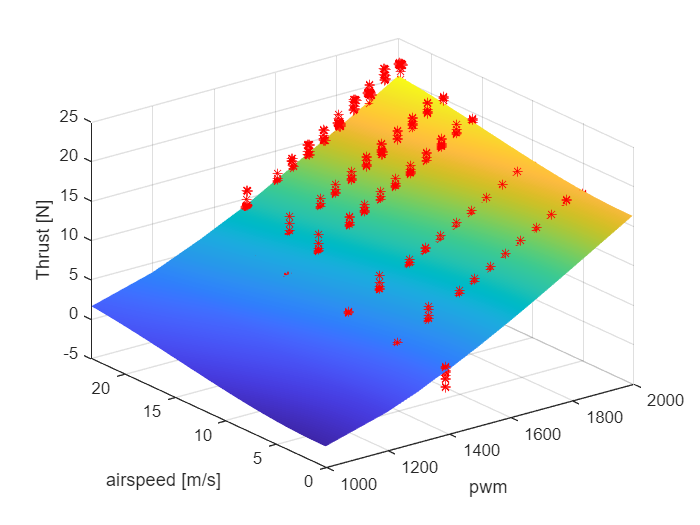

T_total = [poly_T_0.' T_experiment];
pwm_total = [poly_pwm_0.' pwm_experiment];
V_total = ones(size(rpm_q,2),1)*[0,v_q];
%[xm,ym] = meshgrid(pwm_q,as_q);
skipper = 50;
pwm_90_ds = pwm_90(1:skipper:end);
as_rc_90_ds = as_rc_90(1:skipper:end);
thrust_rc_90_ds = thrust_rc_90(1:skipper:end);
[xm,ym] = meshgrid(pwm_90_ds,as_rc_90_ds);

X_vec = [ones(numel(T_total(:)),1)];
%X_vec = [ones(numel(thrust_rc_90_ds),1)];
X_vec_q = [ones(numel(xm(:)),1)];

for ii=1:deg
    X_vec = [X_vec, pwm_total(:).^ii, V_total(:).^ii ];
    %X_vec = [X_vec, pwm_90_ds(:).^ii, as_rc_90_ds(:).^ii ];
    X_vec_q = [X_vec_q, xm(:).^ii,ym(:).^ii ];
end
fitparam = X_vec\T_total(:);
%fitparam = X_vec\thrust_rc_90_ds;
FittedThrust = reshape(X_vec * fitparam,[size(T_total)]);
FittedThrust_q = reshape(X_vec_q * fitparam,[size(xm)]);

figure(58)
clf
surf(xm,ym,FittedThrust_q)
shading interp
hold on 
scatter3(pwm_90(pwm_90>1300), as_rc_90(pwm_90>1300), thrust_rc_90(pwm_90>1300),'*r')

xlabel('pwm')
ylabel(' airspeed [m/s]')
zlabel('Thrust [N]')

### Corrected Momentum Theory Prediction CMT

syms V omega R alpha Mx Fx D rho A
Area(D) = (D/2)^2*pi;
mu(V, alpha, omega, R) = (V * sin(alpha)) / (omega * R);
Pmech(omega, Mx) = omega*Mx;
vi = sqrt(0.5*(-V^2+sqrt(V^4+4*(Fx/(2*rho*A))^2)));%0.5*sqrt((2*(sqrt(A^2*rho^2*V^4+Fx^2)-A*rho*V^2))/(A * rho))
V1 = sqrt((V*sin(alpha))^2+(V*cos(alpha)+vi)^2);
Pi = Fx*(vi+V*cos(alpha));
n_plr = Pi/Pmech;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
N_plr = matlabFunction(n_plr)

N_plr = function_handle with value:
    @(omega,Mx,A,Fx,V,alpha,rho)(Fx.*(sqrt(V.^2.*(-1.0./2.0)+sqrt(V.^4+1.0./A.^2.*Fx.^2.*1.0./rho.^2)./2.0)+V.*cos(alpha)))./(Mx.*omega)


AREA = matlabFunction(Area);
VI = matlabFunction(vi)

VI = function_handle with value:
    @(A,Fx,V,rho)sqrt(V.^2.*(-1.0./2.0)+sqrt(V.^4+1.0./A.^2.*Fx.^2.*1.0./rho.^2)./2.0)


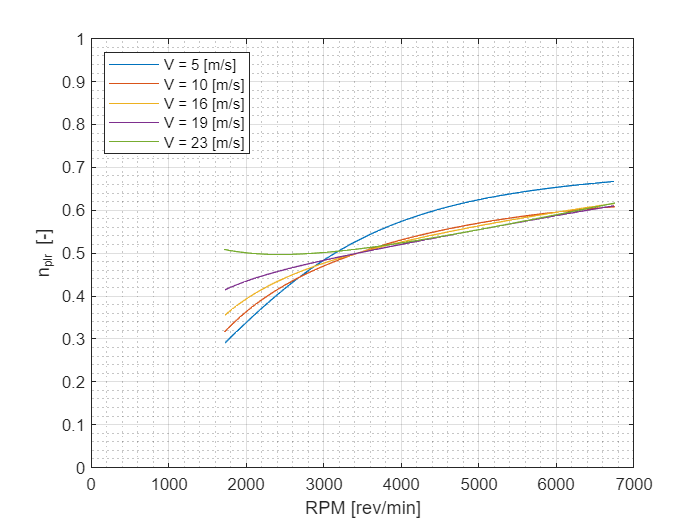

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
A_CMT = AREA(d);
omega_CMT = rpm_q*rpm2rads;
Mx_CMT = Mx_experiment;
Fx_CMT = T_experiment;
alpha_CMT = deg2rad(90);
rho_CMT = mean(MN3510_MF1302R_90_w.Var10./((MN3510_MF1302R_90_w.Var9+273.15).*287)); %1.225;
V_CMT = [5 10 16 19 23];
eff_plr = N_plr(omega_CMT.',Mx_CMT,A_CMT,Fx_CMT,V_CMT, alpha_CMT,rho_CMT);
eff_plr_m = mean(eff_plr);

figure(51)
clf
plot(rpm_q,eff_plr);
ylim([0,1]);
xlim([0,7000])
grid on
grid minor
xlabel('RPM [rev/min]')
ylabel('n_{plr} [-]')
legendStrings = "V = " + string(round(V_CMT))+" [m/s]";
legend(legendStrings,'Location','northwest')

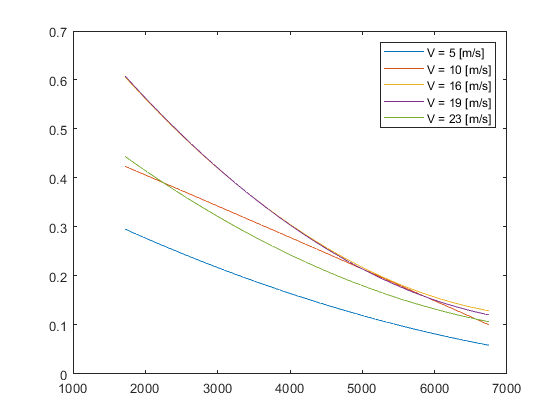


figure(52)
clf
plot(rpm_q,n_plr_experiment);legendStrings = "V = " + string(round([v_q]))+" [m/s]";legend(legendStrings,'Location','northeast')

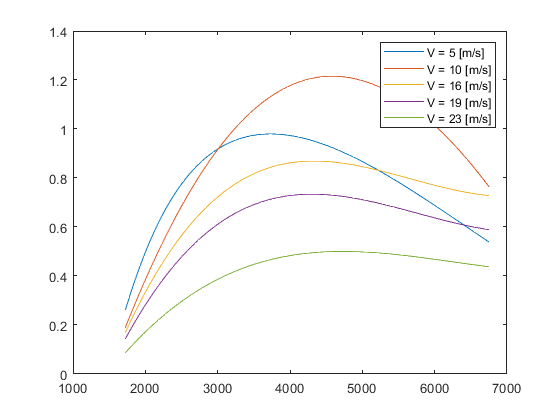

Thrust_CMT= linspace(1, max(max(T_experiment)),100).';
Vi_CMT_2 = VI(A_CMT,Thrust_CMT,v_q,rho_CMT);
figure(53)
plot(rpm_q,n_plr_experiment.*Vi_CMT_2);legendStrings = "V = " + string(round([v_q]))+" [m/s]";legend(legendStrings,'Location','northeast')

Now let's try to recreate plots from the paper


V_CMT_2 = 5:23 %linspace(5,23,50);

V_CMT_2 =      5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23


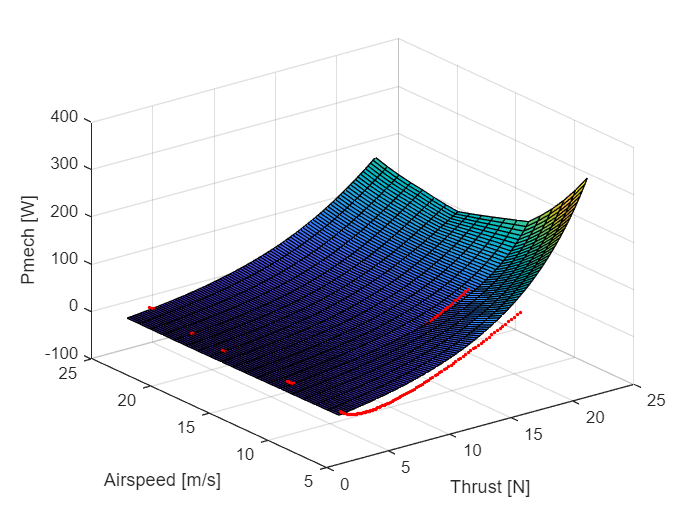

Vi_CMT = VI(A_CMT,Thrust_CMT,V_CMT_2,rho_CMT);
eff_plr_corr3 = zeros(size(n_plr_experiment,1),size(V_CMT_2,2));
%cf = 
X = rad2deg(atan((V_CMT_2.'./(rpm_q.*rpm2rads)./r).'./((V_CMT_2.'./(rpm_q.*rpm2rads)./r).'+Vi_CMT)));
for h =1:size(n_plr_experiment,1)
    eff_plr_corr3(h,:)= interp1(V_CMT,n_plr_experiment(h,:).*Vi_CMT_2(h,:),V_CMT_2);
end

eff_plr_corr = eff_plr;
eff_plr_corr(eff_plr_corr>0.8)=0;
eff_plr_corr = mean(eff_plr_corr);
eff_plr_corr2 = interp1(V_CMT, eff_plr_corr, V_CMT_2 );
%eff_plr_corr3 = interp1(V_CMT,mean(n_plr_experiment.*Vi_CMT_2), V_CMT_2);
P_mech = Vi_CMT.*Thrust_CMT./eff_plr_corr3;
[xm,ym] = meshgrid(Thrust_CMT,V_CMT_2);

[xm2,ym2] = meshgrid(Fx_CMT(:,1), V_CMT);
P_mech2 = omega_CMT.'.*Mx_CMT;
ym2 = ym2.';
figure(52)
clf
surf(xm,ym,P_mech.')
hold on
%scatter3(Fx_CMT(:),ym2(:),P_mech2(:),'.r')
scatter3(T_experiment(:),ym2(:),P_mech_experiment(:),'.r')
xlabel('Thrust [N]')
ylabel('Airspeed [m/s]')
zlabel('Pmech [W]')

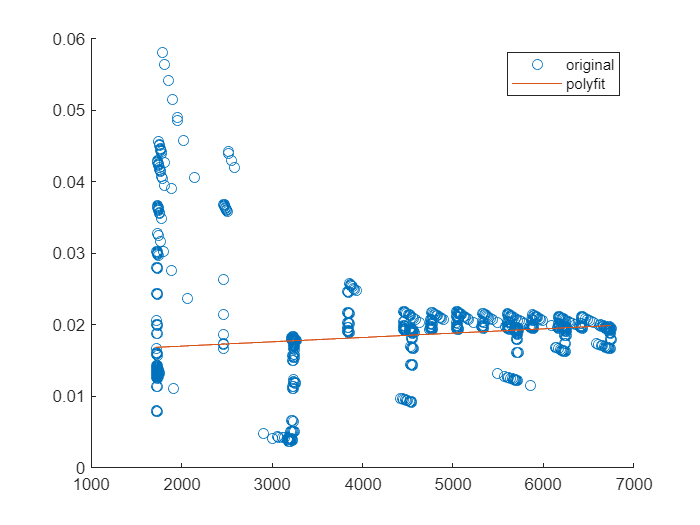



Vt_q = [0  5 10 16 19 23];
range= (rpm_E_00 >rpm_q(1));

rpm_min_0 = roots(polycoeffs_0);
rpm_min_0 = min(rpm_min_0(rpm_min_0>0));
v_min_0 = rpm_min_0*rpm2rads*r;

%rcCL = 1.06 * mean(thrust_rc_00(range)./(rpm_E_00(range)*rpm2rads).^2 .* (3/r^3));
rcCL =thrust_rc_00(range)./(rpm_E_00(range)*rpm2rads).^2 .* (3/r^3);
[coef_rcCL, rccl_v] = poly_gen(rpm_E_00(range),rcCL,1,rpm_q,1);

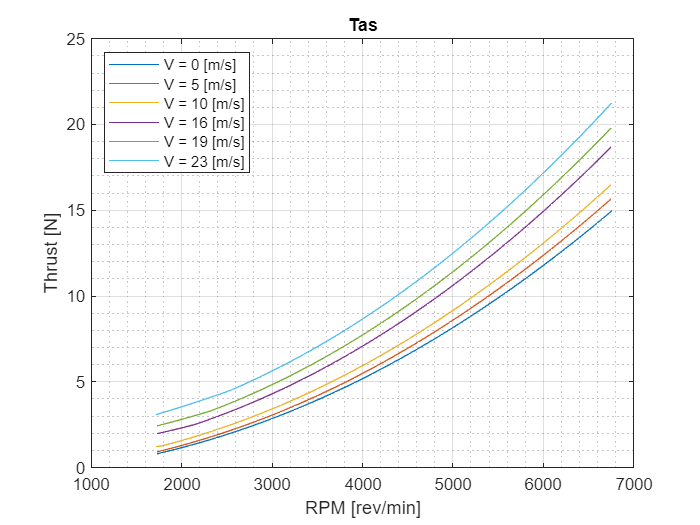


rcCL_aug = [mean(rccl_v),rcCl_experiment];
%test run rccl at higher speeds
% rcCL_23 = thrust_rc_90(idx_s:idx_e)./(rpm_E_90(idx_s:idx_e)*rpm2rads).^2 .* (3/r^3);
% [coef_rcCL_23, rccl_v_23] = poly_gen(rpm_E_90(idx_s:idx_e),rcCL_23,2,rpm_q,1);

fun = @(x,rev,as,rcCL,v_min) 0.5*rcCL*(rev*x+as).^2+0.5*rcCL*min(max(0,rev*x-as-v_min),1).*(rev*x-as).^2;

fun2= @(x,rev,as,rcCL) 0.5*rcCL*(rev*x+as).^2+0.5*rcCL*(rev*x-as).^2;

T_as = zeros(size(rpm_q,2),size(Vt_q,2));
T_as_2 = zeros(size(rpm_q,2),size(Vt_q,2));
for k=1:size(rpm_q,2)
    for j=1:size(Vt_q,2)
        %T_as(k,j)= integral(@(x) fun(x,rpm_q(k)*rpm2rads,Vt_q(j),rccl_v(1,k),v_min_0),0,r);
        T_as(k,j)= integral(@(x) fun(x,rpm_q(k)*rpm2rads,Vt_q(j),rcCL_aug(j),v_min_0),0,r);
        T_as_2(k,j)= integral(@(x) fun2(x,rpm_q(k)*rpm2rads,Vt_q(j),rcCL_aug(j)),0,r);

    end
end
figure(8)
clf
plot(rpm_q,T_as.')
legendStrings = "V = " + string(round(Vt_q))+" [m/s]";
legend(legendStrings,'Location','northwest')
xlabel('RPM [rev/min]')
ylabel('Thrust [N]')
grid on
grid minor
title('Tas')

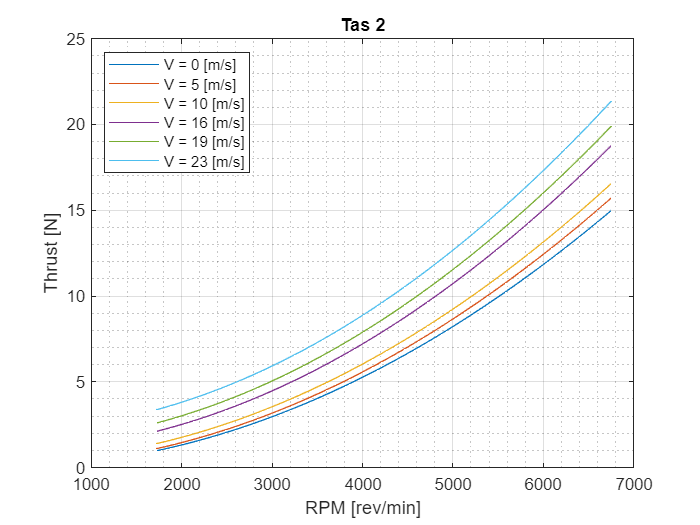


figure(9)
clf
plot(rpm_q,T_as_2.')
legendStrings = "V = " + string(round(Vt_q))+" [m/s]";
legend(legendStrings,'Location','northwest')
xlabel('RPM [rev/min]')
ylabel('Thrust [N]')
grid on
grid minor
title('Tas 2')

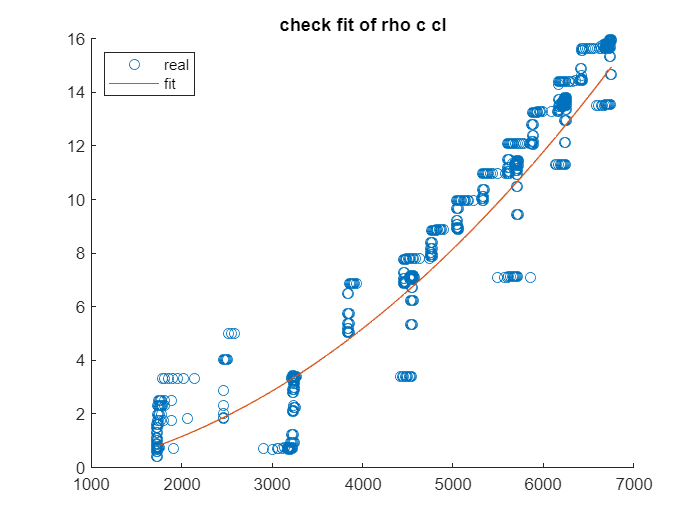


figure(101)
clf
title('check fit of rho c cl')
hold on 
scatter(rpm_E_00(range),thrust_rc_00(range))
plot(rpm_q,T_as(:,1))
legend('real','fit','Location','northwest')

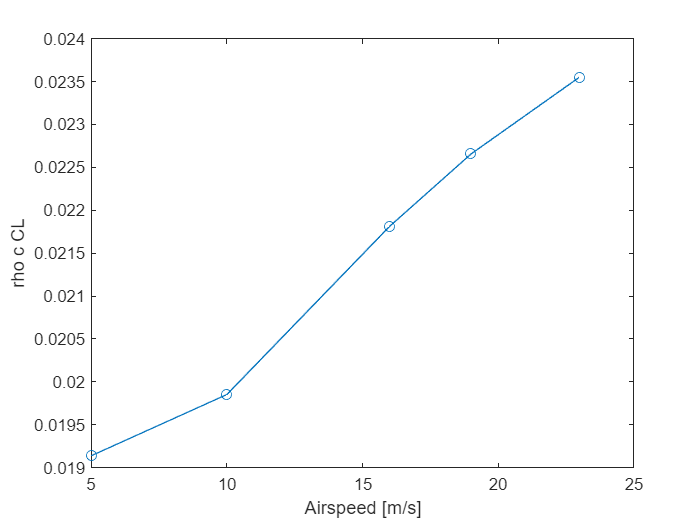


figure(102)
clf
plot(v_q,rcCl_experiment,'-o')
xlabel('Airspeed [m/s]')
ylabel('rho c CL')

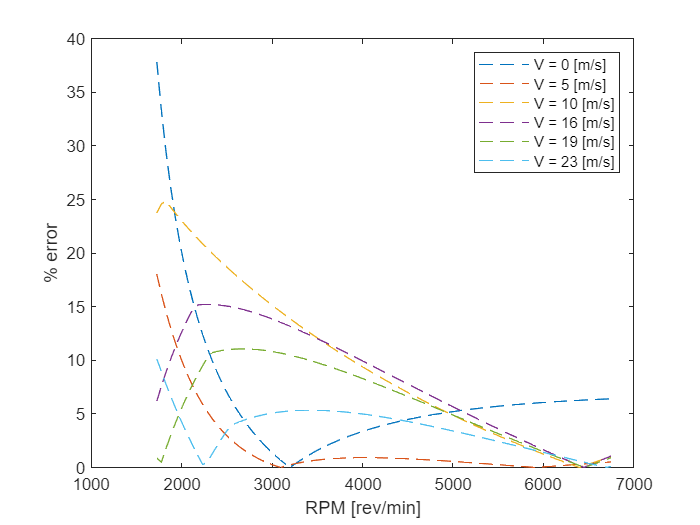


figure(103)
clf
plot(rpm_q,abs((T_as-[poly_T_0.',T_experiment])./[poly_T_0.',T_experiment])*100,'--');legend(legendStrings,'Location','northeast')
xlabel('RPM [rev/min]')
ylabel('% error')

Let's test the correction factor method

rpm_elect = rpm_E_00;
rpm_elect(rpm_elect==0)=0.001;
[rpm_elect,tf] = rmoutliers(rpm_elect,'movmean',200);

time_elect = time_rc_00;
time_elect(tf)=[];
thrust_elect = thrust_rc_00;
thrust_elect(tf)=[];
